# Continuous Population Models I: Exponential Growth

**Mathematical skills:** arithmetics, equations, functions, graphs

**Coding extras:** Tables, solving differential equations with conditions, plots, assigning values, symbolics

**Physics skills: **conversions, dimensional analysis  

**Task: **Read the intro. Then, modify the code to answer the questions in the Questions section. 

**Criteria**: You may notice that the lessons are getting longer and a bit more complex. So, you might be wondering what do I really need from this tutorial? Here are some checkpoints:

- Can you change the code so that the initial population density is what you want?

- Can you change the code so that the initial reproduction rate is what you want?

- Can you identify the symbol that corresponds to the initial population density?

- Can you identify the symbol that corresponds to the reproduction rate?

- Can you describe in your own words what the graphs look like? Here are some phrases that may be useful: nonlinear, changing faster than linear, strictly increasing/decreasing (it is okay if some of these are unfamiliar as long as visually you can tell a linear graph from an exponential one)

If the answer to these is yes, you're all set! If you're really stuck, inform your instructor ASAP!

## Intro

In the models that we have explored so far, we have considered generations, steps, or similar concepts all of which are ***discrete***. For many applications, however, time is a ***continuous*** variable. 

Here's one way to differentiate between these two types of models within this context:

**Discrete**: think 'countable' or 'zero or finite number of points between two points'. For example, there is one generation between the first generation and the third generation. 

**Continuous**: infinite points between each two points. Take 1 second after an event and 2 seconds after. We can talk about 1.5 seconds after the event, or 1.55 seconds, or 1.55555 seconds. There are infinite time instances between these time instances! There is no limit to how thin you can slice a second.

    Discrete population models are generally more appropriate for populations with distinct steps in their life cycles, like insects. Even then, they are sometimes used with continuous models in a hybrid form. In the *As Good As New* story, we could have used a discrete model to describe the segmental growth of the deadly fungus. To model the decline of the human population in that story, however, a continous model would be more appropriate. That's not to say discrete models don't have their advantages. Most numerical approaches (for example, using a computer to solve more complex equations) rely on creating a discrete version of the continuous models.

Here, we run an example to model the population of bacteria as a function of (continuous) time given *ideal growth circumstances*. 

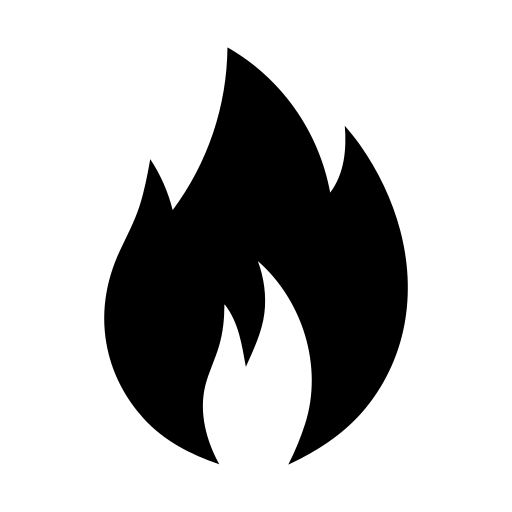**Hot** **Question:** What does *ideal growth circumstances* mean?

    As usual, we need some assumptions to simplify the model. Given an initial bacterial density, `N0`, we will see how the bacterial density $N\left(t\right)$ changes with respect to time `t` if its rate of reporoduction per unit time is `K`. In this example, we assume that the colony has access to *undepletable* resources. Note that here we are talking about density (cells per volume) instead of number of cells. Usually, this is more helpful for growing microorganisms in the lab in a fluid that contains nutrients for their growth.

**Hot** **Question:** How do we use the rate of growth, K, to calculate the amount of growth in a time interval $\Delta t$?

If N0 is the density initially, K tells us how much additional density we will have after the time interval $\Delta t$ (we usually use the greek letter $\Delta$(delta) to denote change in a variable):

**[increase (or decrease) in density after **$\Delta t$**] = **${K\times N}_0 \times \Delta t$ 

Let's denote the population density at time t by `N(t). `In continuous models, we had difference equations. Here, we can calculate N(t) by solving 

$\frac{\mathrm{dN}}{\mathrm{dt}\;}=\mathrm{KN}$,                            Equation 1

with the initial value of N0 given. This is a ***differential equation*****.** This one specificially is sometimes called the *Malthus law*. In this course, we will not cover solving these equations manually. Instead, we will use MATLAB to solve this. To see the details of the code, head to the functions section. We can solve this equation *analytically *and the solution is an **exponential** function: 

$N\left(t\right)=N_{0\;} e^{\textrm{Kt}} \ldotp$                Equation 2

## Code

After a relatively hefty intro, here we are, at the section that you will modify later to use. 

First, we set the initial population density `N0` and,` T_final,` the final time that we are interested in, say 12 hours later:

N0 = 1000000; % unit:cells/ml 
T_final = 6; % unit: hours

and the rate of reporoduction per hour,` K`:

K =0;

**Tip:** use the slider to play with the value of` K` and watch how it changes the final population density.

Now, we use a MATLAB symbolic solver to solve Equation 1. If you would like to see the details, head to the functions section and look at the code used for the function `ContPopModelExp(K,N0)`.

ExpModel = ContPopModelExp(K,N0)

$$ExpModel(t) = 1000000$$

This type of growth is known as **exponential growth**. The table below shows the value of the population density at different times:

Times = [0;1/60; 1; 6; 24]; % [1 minute, 1 hour, 6 hours, 1 day]
N_values = double(ExpModel(Times))

N_values =      1000000
     1000000
     1000000
     1000000
     1000000


T = table(Times, N_values)

T = 5×2 table
     Times      N_values
    ________    ________

           0     1e+06  
    0.016667     1e+06  
           1     1e+06  
           6     1e+06  
          24     1e+06  


## Graphs 1

Visualization of data usually helps us better understand it. Here, we graph the population density N(t) as a function of time:

fplot(ExpModel,[0 T_final], 'LineWidth',3)
xlabel('time (hour)')
ylabel('population density (cells/ml)')

## Questions

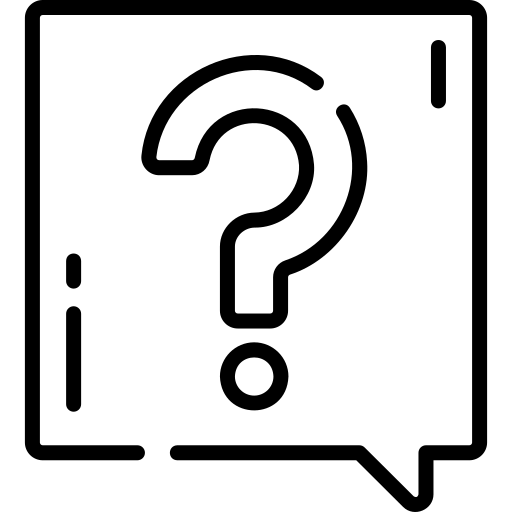 **Question 1:** What is the population density after 1 hour when K = 1 and N0 = 1,000,000 cells/ml?

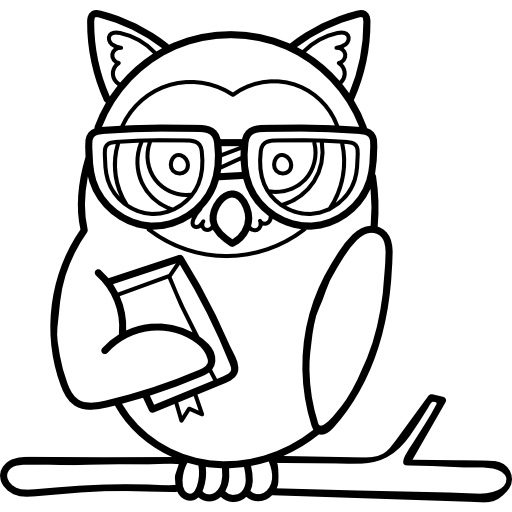  **Owl Tip: **You can either use the table above or the following snippet of code in the command line for a quick answer. Make sure you set       K = 1 in the code and run it first!

 **Question 2:** What is the population density after 2 hours when K = 1 and N0 = 1,000,000 cells/ml?

 **Question 3:** By how much does the population change after an hour when K = 1 and N0 = 1,000,000 cells/ml?

  **Owl Tip: **You can either use the table above or the following snippet of code in the command line for a quick answer.

 **Question 4:** What happens to the population density when K is negative?

 **Question 5:** The MATLAB solver gave us a ***symbolic*** expression as a solution to Equation 1. What is the difference between the outcomes of running these two snippets of code?

                or

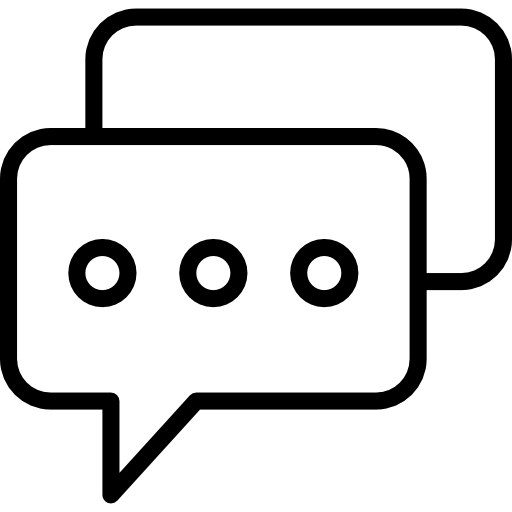 **Question 6:** What does this model tell us about the "uncontrolled growth" or exponential growth? What are the limitations of this model?

 **Question 7:** identify the sticky points: what concepts are still confusing? What more examples can help? What skills do you need more help with?

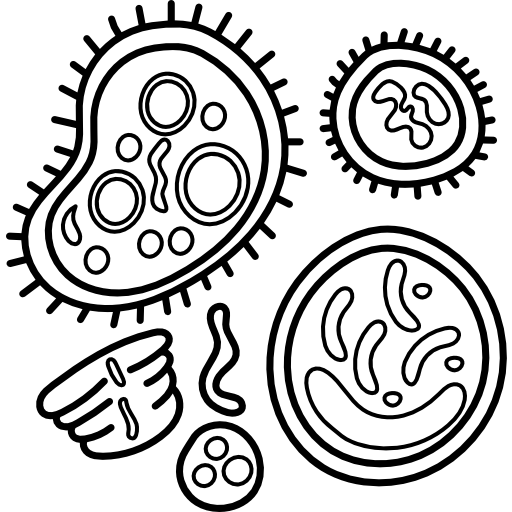summarize what you have learned using your own words.

#### Bonus: exploring the continious limit

In the previous sessions, we focused on discrete models. We talked about generations and steps. In the continous limit, we think about extremely small time steps $\Delta t\;$ where $\Delta t\;\to 0$. If you are interested in learning more, read section 4.1 in **Mathematical Models in Biology** by Leah Edelestein-Keshet. Or ask during student hours!

## Functions

function ExpModel = ContPopModelExp(K,N0)
syms  N(t)
eqn = diff(N, t) == K*N;
cond = N(0) == N0;
ExpModel(t) = dsolve(eqn,cond);

end